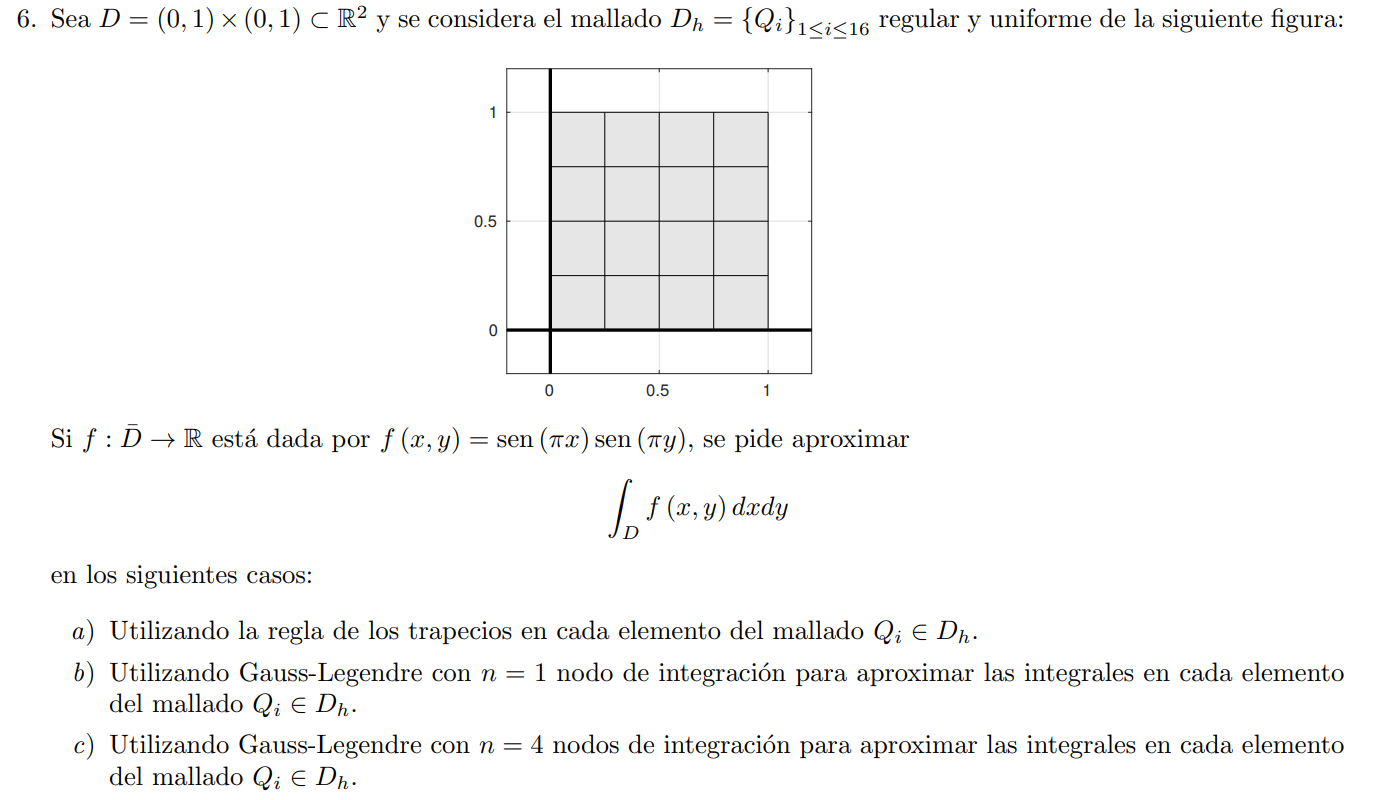

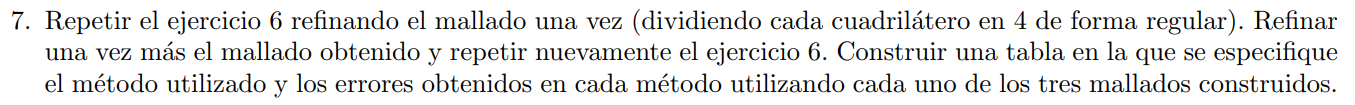

clear
format long
f=@(x,y) sin(pi*x).*sin(pi*y);
%VALOR REAL
q = integral2(f,0,1,0,1)

q =    0.405284734552890


%Método de los trapecios con los 3 tipos de mallado
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1
        X1=[xi(i);yi(j)];    
        X2=[xi(i+1);yi(j)];
        X3=[xi(i+1);yi(j+1)];
        X4=[xi(i);yi(j+1)];

        

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))...
            +f(X4(1),X4(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.364276695296637


ans =    0.394908474517003


ans =    0.402683081718037


%GL n=1 con los 3 mallados
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);
mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1

%         X1=[xi(i);yi(j)];    
%         X2=[xi(i+1);yi(j)];
%         X3=[xi(i+1),yi(j+1)];
%         X4=[xi(i),yi(j+1)];

        X0=[xi(i)+h/2;yi(j)+h/2];

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        Qf=Qf+area*0.25*4*(f(X0(1),X0(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.426776695296637


ans =    0.410533474517003


ans =    0.406589331718037


%GL n=4
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;
for i=1:length(xi)-1
    for j=1:length(yi)-1
        X1=[xi(i)+h/sqrt(3);yi(j)+h/sqrt(3)];    
        X2=[xi(i+1)-h/sqrt(3);yi(j)+h/sqrt(3)];
        X3=[xi(i+1)-h/sqrt(3);yi(j+1)-h/sqrt(3)];
        X4=[xi(i)+h/sqrt(3);yi(j+1)-h/sqrt(3)];

        

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        %para n=4 los pesos son 1 viva!!!

        Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))...
            +f(X4(1),X4(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.425203546599088


ans =    0.410154806668768


ans =    0.406495552625566
